%calculating the mean first passage time analytically/numerically 
%to investigate effect of incumbent-substrate mismatch position on DNA/DNA
%toehold exchange kinetics including spotaneous incumbent dissociation

b = 20 %define branch migration domain length

b =     20


g = 4 %define invader toehold length

g =      4


g2 = 1 %define incumbent toehold length 

g2 =      1



bg2 = b + g2 %define branch migration domain + incumbent toehold length

bg2 =     21




R = 1.987/1000 %universal gas constant in kcal/K/mol 

R =    0.001987000000000


temp = 298.15 %temperature in K

temp =      2.981500000000000e+02


%free energy parameters
dGassoc = 2.6*R*temp

dGassoc =    1.540302530000000


dGbp = -2.52*R*temp

dGbp =   -1.492908606000000


dGp = 3.6*R*temp

dGp =    2.132726580000000


dGmm = 9.5 *R*temp

dGmm =    5.628028475000000


dGbm = 7.4*R*temp

dGbm =    4.383937970000000


%absolute rate constant
k_bp = 5.4*10^7

k_bp =     54000000


k_eff = zeros(1,20)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 20)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 20)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(1, 20)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(1, 20)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(1, 20)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



dGbox_avr = zeros(20, b)

dGbox_avr =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0  


%loop through mismatch positions
for m = 1:20
    %loop through states prior to mismatch (in branch migration domain) and
    %define free energy
    for state = 1:m-1 
        dGbox_avr(m, state) = - R*temp*log(exp(-(-dGbp*(m - state) + dGp)/(R*temp)) + exp(-(dGmm + dGp)/(R*temp)))
    end
    %define free energy for states after mismatch (in branch migration
    %domain)
    dGbox_avr(m, :) = horzcat(dGbox_avr(m, 1:m-1), repmat(dGp, [1, b-m+1]))

    %define free energy of final state in invader toehold 
    dGboxC1 = - R*temp*log(exp(-(-dGbp*(m-0) + dGp)/(R*temp)) + exp(-(dGmm)/(R*temp)))
    
    format long 
    trans_state = (-dGbp)*(b + g2-1)
    react_coord = zeros(1, b-1)
    %loop through states prior to mismatch and define free energy (in terms
    %of incumbent dissociation)
    for state = 1:m-1
        react_coord(state) = -R*temp*log(exp(-(state*-dGbp + dGmm)/(R*temp)) + exp(-(state*-dGbp)/(R*temp)))
    end
    %loop through states after mismatch and define free energy (in terms of
    %incumbent dissociation)
    for state = m:b-1
        react_coord(state) = state*-dGbp
    end
    react_coord = flip(react_coord);
    
    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_C1rm = k_bp * exp(-(dGboxC1 - dGbox_avr(m, 1) + dGbm)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    
    k_Crbm = zeros(1, m-2);
    for state = 2:m
        k_Crbm(state-1) = k_bp * exp(-(dGbox_avr(m, state-1) - dGbox_avr(m, state) + dGbm)/(R*temp))
    end
    k_Crm_end = k_bp * exp(-(0 - dGbox_avr(m, b-1) + dGbm)/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    %k_DC = k_bp * exp(-(dGbm + dGbox_avr(m, 19))/(R*temp))
    k_DC = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_DEij = k_bp * exp(dGbp/(R*temp))
    k_DEji = k_bp;
    k_EF = k_bp * exp(dGbp/(R*temp));
    k_FE = 0
    k_FF = 1    
    
    %create arrays of forward and reverse transition rates for
    %mismatch-free systems
    Kf_perf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb_perf = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
    %define spontaneous incumbent dissociation rates for mismatch-free
    %system
    Koff_perf = [repmat(0, [1, g2+1])]; 
    for n = g2+1:bg2-1
        Koff_perf = horzcat(Koff_perf, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
    end
    Koff_perf = horzcat(Koff_perf, [repmat(0, [1, g+1])])
       
    if g == 1
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-m]), flip(k_Cfbm), k_Cf, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_C1rm, k_B1A, k_AA]
        
        %define spontaneous incumbent dissociation rates for mismatch
        %system
        Koff = [repmat(0, [1, g2+1])];
        for n = 1:b-1
            Koff = horzcat(Koff, [k_bp*exp(-(-dGbp)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
        end
        Koff = horzcat(Koff, [0, 0])
        
    else
        %create arrays of forward and reverse transition rates for mismatch
        %system
        if m == b
            Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_Cf, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
            Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_Crm_end, flip(k_Crbm(1:m-2)), k_C1rm, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        else
            Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_Cf, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
            Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-m-1]), flip(k_Crbm), k_C1rm, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        end
      
        %define spontaneous incumbent dissociation rates for mismatch
        %system
        Koff = [repmat(0, [1, g2+1])]; 
        for n = 1:b-1
            Koff = horzcat(Koff, [k_bp*exp(-(-dGbp)/(R*temp))*exp(-(trans_state - react_coord(n))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
    end
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
            
    %calculate flux between each state for mismatch system
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
    end
        
    Pn_jN_1_perf = zeros(1,numel(Kf_perf))
    jn_jN_1_perf = zeros(1,numel(Kf_perf))
    Pn_jN_1_perf (1) = 0;
    jn_jN_1_perf (1) = 1;
            
    %calculate flux between  each state for mismatch-free system
    for Pn = 2:numel(Kf_perf)
        Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf (Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
        jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + Koff_perf(Pn) * Pn_jN_1_perf(Pn);
    end
    
    first_pass_time (m) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %calculate first passage time for mismatch system
    k_eff (m) = 1/(first_pass_time (m)*(5*10^-8));%calculate effective rate constant for mismatch system
    prob_unbound(m) = Pn_jN_1(end)/sum(Pn_jN_1)%calculate prob of being in unbound state for mismatch system
    
    first_pass_time_perf (m) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf) %calculate first passage time for mismatch-free system
    k_eff_perf (m) = 1/(first_pass_time_perf (m)*(5*10^-8));%calculate effective rate constant for mismatch-free system
    prob_unbound_perf(m) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf)%calculate prob of being in unbound state for mismatch-free system
end

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
                   0                   0                   0                   0                   0                   0                   0                   0                   0      

dGboxC1 =    3.605800432260688


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492908606000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492908606000000   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      2.746205099702222e+03


k_Cf =      3.300764910099690e+04


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf = 	1.0e+07 *

   0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf = 	1.0e+06 *

                   0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf = 	1.0e+05 *

                   0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf = 	1.0e+07 *

   0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb = 	1.0e+06 *

                   0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002746205099702   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff = 	1.0e+05 *

                   0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    6.263727371242918                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf = 	1.0e+02 *

   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0
                   0                   0                   0                   0                   0                   0                   0                   0                   0      

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
                   0                   0                   0                   0                   0                   0                   0                   0                   0      

dGboxC1 =    4.909488473760101


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985817212000000   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      3.776095990858597e+03


k_Cf =      3.300764910099690e+04


k_Crbm =      2.658253149328268e+03


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.003776095990859   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    6.263727371242918   5.859685851409131                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258                   0                   0                   0                   0                   0                   0                   0                   0      

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604                   0                   0                   0                   0                   0                   0                   0      

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.524905167117471


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478725818000000   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.643335951958519e+04


k_Cf =      3.300764910099690e+04


k_Crbm =      2.683992661111686e+03


k_Crbm =    2.683992661111686   2.658253149328268


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.016433359519585   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    6.263727371242918   5.859685851409131   5.969737286193235                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.619033898885303


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971634424000000   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.541074238374548e+05


k_Cf =      3.300764910099690e+04


k_Crbm =    3.002710467293847                   0


k_Crbm =    3.002710467293847   2.683992661111686


k_Crbm =    3.002710467293847   2.683992661111686   2.658253149328268


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.154107423837455   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    6.263727371242918   5.859685851409131   5.969737286193235   7.535197636491810                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.627299701621379


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464543030000001   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      7.753765722320332e+05


k_Cf =      3.300764910099690e+04


k_Crbm =    6.469429450270415                   0                   0


k_Crbm =    6.469429450270415   3.002710467293847                   0


k_Crbm =    6.469429450270415   3.002710467293847   2.683992661111686


k_Crbm =    6.469429450270415   3.002710467293847   2.683992661111686   2.658253149328268


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.775376572232033   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    6.263727371242918   5.859685851409131   5.969737286193235   7.535197636491810  15.541538762939965                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.627969805004818


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957451636000000  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.156061665180628e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    2.211337488725873                   0                   0                   0


k_Crbm =    2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   1.156061665180628   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    6.263727371242918   5.859685851409131   5.969737286193235   7.535197636491810  15.541538762939965  27.504900569371085                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628023754220313


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450360242000000  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.203668440380679e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   0.031699263448041   1.203668440380679   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    6.263727371242918   5.859685851409131   5.969737286193235   7.535197636491810  15.541538762939965  27.504900569371085  39.970551552309161                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028095166530


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943268848000001  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.207670253188868e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.289803180083173                   0                   0                   0                   0                   0


k_Crbm =    3.289803180083173   3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.289803180083173   3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   0.031699263448041   0.032898031800832   1.207670253188868   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    6.263727371242918   5.859685851409131   5.969737286193235   7.535197636491810  15.541538762939965  27.504900569371085  39.970551552309161  52.479446655702915                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831   0.999871516587540                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028444438740


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436177454000001  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.207993396968601e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.299879994839243                   0                   0                   0                   0                   0                   0


k_Crbm =    3.299879994839243   3.289803180083173                   0                   0                   0                   0                   0


k_Crbm =    3.299879994839243   3.289803180083173   3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   0.031699263448041   0.032898031800832   0.032998799948392   1.207993396968601   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    6.263727371242918   5.859685851409131   5.969737286193235   7.535197636491810  15.541538762939965  27.504900569371085  39.970551552309161  52.479446655702915  64.991972862240232                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831   0.999871516587540   0.999880373513324                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028472541053


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929086060000001  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.208019404523514e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.300693691072436                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300693691072436   3.299879994839243                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300693691072436   3.299879994839243   3.289803180083173                   0                   0                   0                   0                   0


k_Crbm =    3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   0.031699263448041   0.032898031800832   0.032998799948392   0.033006936910724   1.208019404523514   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    6.263727371242918   5.859685851409131   5.969737286193235   7.535197636491810  15.541538762939965  27.504900569371085  39.970551552309161  52.479446655702915  64.991972862240232  77.504853797462360                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831   0.999871516587540   0.999880373513324   0.999885589138543                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028474802154


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421994666000000  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.208021497129939e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.300759179721123                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300759179721123   3.300693691072436                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300759179721123   3.300693691072436   3.299879994839243                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173                   0                   0                   0                   0                   0


k_Crbm =    3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   0.031699263448041   0.032898031800832   0.032998799948392   0.033006936910724   0.033007591797211   1.208021497129939   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    6.263727371242918   5.859685851409131   5.969737286193235   7.535197636491810  15.541538762939965  27.504900569371085  39.970551552309161  52.479446655702915  64.991972862240232  77.504853797462360  90.017819532915937                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831   0.999871516587540   0.999880373513324   0.999885589138543   0.999888681792374                   0                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028474984081


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914903272000000  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.208021665500544e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.300764449034888                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764449034888   3.300759179721123                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764449034888   3.300759179721123   3.300693691072436                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173                   0                   0                   0                   0                   0


k_Crbm =    3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   0.031699263448041   0.032898031800832   0.032998799948392   0.033006936910724   0.033007591797211   0.033007644490349   1.208021665500544   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.062637273712429   0.058596858514091   0.059697372861932   0.075351976364918   0.155415387629400   0.275049005693711   0.399705515523092   0.524794466557029   0.649919728622402   0.775048537974624   0.900178195329159   1.025308478478669                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831   0.999871516587540   0.999880373513324   0.999885589138543   0.999888681792374   0.999890428729428                   0                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028474998719


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407811878000000  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.208021679047578e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.300764873002597                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764873002597   3.300764449034888                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764873002597   3.300764449034888   3.300759179721123                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173                   0                   0                   0                   0                   0


k_Crbm =    3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   0.031699263448041   0.032898031800832   0.032998799948392   0.033006936910724   0.033007591797211   0.033007644490349   0.033007648730026   1.208021679047578   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.062637273712429   0.058596858514091   0.059697372861932   0.075351976364918   0.155415387629400   0.275049005693711   0.399705515523092   0.524794466557029   0.649919728622402   0.775048537974624   0.900178195329159   1.025308478478669   1.150439369110867                   0                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831   0.999871516587540   0.999880373513324   0.999885589138543   0.999888681792374   0.999890428729428   0.999891269052869                   0                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028474999897


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900720484000001                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900720484000001  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900720484000001  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900720484000001  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.208021680137568e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.300764907114871                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764907114871   3.300764873002597                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764907114871   3.300764873002597   3.300764449034888                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173                   0                   0                   0                   0                   0


k_Crbm =    3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   0.031699263448041   0.032898031800832   0.032998799948392   0.033006936910724   0.033007591797211   0.033007644490349   0.033007648730026   0.033007649071149   1.208021680137568   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.062637273712429   0.058596858514091   0.059697372861932   0.075351976364918   0.155415387629400   0.275049005693711   0.399705515523092   0.524794466557029   0.649919728622402   0.775048537974624   0.900178195329159   1.025308478478669   1.150439369110867   1.275570865128196                   0                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831   0.999871516587540   0.999880373513324   0.999885589138543   0.999888681792374   0.999890428729428   0.999891269052869   0.999891469549291                   0                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028474999992


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393629090000001                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393629090000001  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393629090000001  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393629090000001  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.208021680225267e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.300764909859537                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764909859537   3.300764907114871                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764909859537   3.300764907114871   3.300764873002597                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173                   0                   0                   0                   0                   0


k_Crbm =    3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   0.031699263448041   0.032898031800832   0.032998799948392   0.033006936910724   0.033007591797211   0.033007644490349   0.033007648730026   0.033007649071149   0.033007649098595   1.208021680225267   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787089808   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.062637273712429   0.058596858514091   0.059697372861932   0.075351976364918   0.155415387629400   0.275049005693711   0.399705515523092   0.524794466557029   0.649919728622402   0.775048537974624   0.900178195329159   1.025308478478669   1.150439369110867   1.275570865128196   1.400702956883243                   0                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831   0.999871516587540   0.999880373513324   0.999885589138543   0.999888681792374   0.999890428729428   0.999891269052869   0.999891469549291   0.999891201580325                   0                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028474999999


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886537696000001                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886537696000001  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886537696000001  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886537696000001  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.208021680232327e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.300764910080363                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910080363   3.300764909859537                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910080363   3.300764909859537   3.300764907114871                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173                   0                   0                   0                   0                   0


k_Crbm =    3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   0.031699263448041   0.032898031800832   0.032998799948392   0.033006936910724   0.033007591797211   0.033007644490349   0.033007648730026   0.033007649071149   0.033007649098595   0.033007649100804   1.208021680232326   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820888226435   0.000146496985066   0.000011787089808   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.062637273712429   0.058596858514091   0.059697372861932   0.075351976364918   0.155415387629400   0.275049005693711   0.399705515523092   0.524794466557029   0.649919728622402   0.775048537974624   0.900178195329159   1.025308478478669   1.150439369110867   1.275570865128196   1.400702956883243   1.525835507075922                   0                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831   0.999871516587540   0.999880373513324   0.999885589138543   0.999888681792374   0.999890428729428   0.999891269052869   0.999891469549291   0.999891201580325   0.999890580024523                   0                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028475000000


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379446302000002                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379446302000002  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379446302000002  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.208021680232893e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.300764910098137                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910098137   3.300764910080363                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173                   0                   0                   0                   0                   0


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   0.031699263448041   0.032898031800832   0.032998799948392   0.033006936910724   0.033007591797211   0.033007644490349   0.033007648730026   0.033007649071149   0.033007649098595   0.033007649100804   0.033007649100981   1.208021680232893   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022631085335820   0.001820751939821   0.000146496985066   0.000011787089808   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.062637273712429   0.058596858514091   0.059697372861932   0.075351976364918   0.155415387629400   0.275049005693711   0.399705515523092   0.524794466557029   0.649919728622402   0.775048537974624   0.900178195329159   1.025308478478669   1.150439369110867   1.275570865128196   1.400702956883243   1.525835507075922   1.650966669956788                   0                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831   0.999871516587540   0.999880373513324   0.999885589138543   0.999888681792374   0.999890428729428   0.999891269052869   0.999891469549291   0.999891201580325   0.999890580024523   0.999889685591189                   0                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028475000000


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324  26.872354908000002                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324  26.872354908000002  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.208021680232937e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.300764910099573                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.033007649100997   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   0.031699263448041   0.032898031800832   0.032998799948392   0.033006936910724   0.033007591797211   0.033007644490349   0.033007648730026   0.033007649071149   0.033007649098595   0.033007649100804   0.033007649100981   0.033007649100996   1.208021680232936   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281272631697906   0.022629391484458   0.001820751939821   0.000146496985066   0.000011787089808   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.062637273712429   0.058596858514091   0.059697372861932   0.075351976364918   0.155415387629400   0.275049005693711   0.399705515523092   0.524794466557029   0.649919728622402   0.775048537974624   0.900178195329159   1.025308478478669   1.150439369110867   1.275570865128196   1.400702956883243   1.525835507075922   1.650966669956788   1.776073372167329                   0                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831   0.999871516587540   0.999880373513324   0.999885589138543   0.999888681792374   0.999890428729428   0.999891269052869   0.999891469549291   0.999891201580325   0.999890580024523   0.999889685591189   0.999888590518587                   0                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028475000000


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324  26.872310565635324                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324  26.872310565635324  28.365263514000002


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.208021680232943e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.300764910099676                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.208021680232943e+06


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   0.000901891842673   0.002658253149328   0.002683992661112   0.003002710467294   0.006469429450270   0.022113374887259   0.031699263448041   0.032898031800832   0.032998799948392   0.033006936910724   0.033007591797211   0.033007644490349   0.033007648730026   0.033007649071149   0.033007649098595   0.033007649100804   0.033007649100981   0.033007649100996   0.033007649100997   1.208021680232943   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff =                    0                   0   3.495824091876277   0.281251579502522   0.022629391484458   0.001820751939821   0.000146496985066   0.000011787089808   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.062637273712429   0.058596858514091   0.059697372861932   0.075351976364918   0.155415387629400   0.275049005693711   0.399705515523092   0.524794466557029   0.649919728622402   0.775048537974624   0.900178195329159   1.025308478478669   1.150439369110867   1.275570865128196   1.400702956883243   1.525835507075922   1.650966669956788   1.776073372167329   1.900918388713361                   0


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831   0.999871516587540   0.999880373513324   0.999885589138543   0.999888681792374   0.999890428729428   0.999891269052869   0.999891469549291   0.999891201580325   0.999890580024523   0.999889685591189   0.999888590518587   0.999887414276285                   0


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050                   0


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798                   0


dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGbox_avr =    2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000
   5.111733267355258   3.625084308210604   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.132726580000000   2.1

dGboxC1 =    5.628028475000000


trans_state =   29.858172120000003


react_coord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


react_coord =    1.492864263635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323                   0                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322                   0                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322                   0                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323                   0                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323                   0                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323                   0                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320                   0                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324                   0                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324  26.872310565635324                   0


react_coord =    1.492864263635321   2.985772869635321   4.478681475635321   5.971590081635320   7.464498687635322   8.957407293635322  10.450315899635321  11.943224505635321  13.436133111635323  14.929041717635323  16.421950323635322  17.914858929635322  19.407767535635323  20.900676141635323  22.393584747635323  23.886493353635320  25.379401959635324  26.872310565635324  28.365219171635321


k_AB1 =    0.200538661178701


k_B1A =      4.344818764474750e+06


k_C1f =      9.018918426732656e+02


k_C1rm =      1.208021680232943e+06


k_Cf =      3.300764910099690e+04


k_Crbm =    3.300764910099690                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888                   0                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123                   0                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436                   0                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243                   0                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173                   0                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120                   0                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873                   0                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041                   0                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385                   0


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169


k_Crbm =    3.300764910099690   3.300764910099676   3.300764910099573   3.300764910098137   3.300764910080363   3.300764909859537   3.300764907114871   3.300764873002597   3.300764449034888   3.300759179721123   3.300693691072436   3.299879994839243   3.289803180083173   3.169926344804120   2.211337488725873   0.646942945027041   0.300271046729385   0.268399266111169   0.265825314932827


k_Crm_end =      1.500005962095886e+07


k_DC =      9.018918426732656e+02


k_DEij =      4.344818764474750e+06


k_FE =      0


k_FF =      1


Kf_perf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.000090189184267   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb_perf =                    0   0.000901891842673   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   0.033007649100997   4.344818764474750   4.344818764474750   4.344818764474750   4.344818764474750                   0


Koff_perf =                    0                   0   3.495824091876278   0.281272631697907   0.022631085335820   0.001820888226435   0.000146507950634   0.000011787972094   0.000000948455599   0.000000076312365   0.000000006140063   0.000000000494027   0.000000000039749   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Kf =    0.000000100000000   0.434481876447475   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   0.003300764910100   5.400000000000000   5.400000000000000   5.400000000000000   0.000000020053866


Kb =                    0   1.500005962095885   0.000268399266111   0.000300271046729   0.000646942945027   0.002211337488726   0.003169926344804   0.003289803180083   0.003299879994839   0.003300693691072   0.003300759179721   0.003300764449035   0.003300764873003   0.003300764907115   0.003300764909860   0.003300764910080   0.003300764910098   0.003300764910100   0.003300764910100   0.003300764910100   0.120802168023294   0.434481876447475   0.434481876447475   0.434481876447475   0.434481876447475                   0


Koff =                    0                   0   3.495562442630944   0.281251579502522   0.022629391484458   0.001820751939821   0.000146496985066   0.000011787089808   0.000000948384611   0.000000076306653   0.000000006139603   0.000000000493990   0.000000000039746   0.000000000003198   0.000000000000257   0.000000000000021   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000                   0                   0                   0                   0                   0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    0.062637273712429   0.058596858514091   0.059697372861932   0.075351976364918   0.155415387629400   0.275049005693711   0.399705515523092   0.524794466557029   0.649919728622402   0.775048537974624   0.900178195329159   1.025308478478669   1.150439369110867   1.275570865128196   1.400702956883243   1.525835507075922   1.650966669956788   1.776073372167329   1.900918388713361   2.023674541418716


prob_unbound =    0.999213552879305   0.999243806314509   0.999333475518746   0.999509641629561   0.999738435404851   0.999823123624430   0.999855603278831   0.999871516587540   0.999880373513324   0.999885589138543   0.999888681792374   0.999890428729428   0.999891269052869   0.999891469549291   0.999891201580325   0.999890580024523   0.999889685591189   0.999888590518587   0.999887414276285   0.999886252599082


first_pass_time_perf =    2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050   2.353725234402050


prob_unbound_perf =    0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798   0.999885282961798


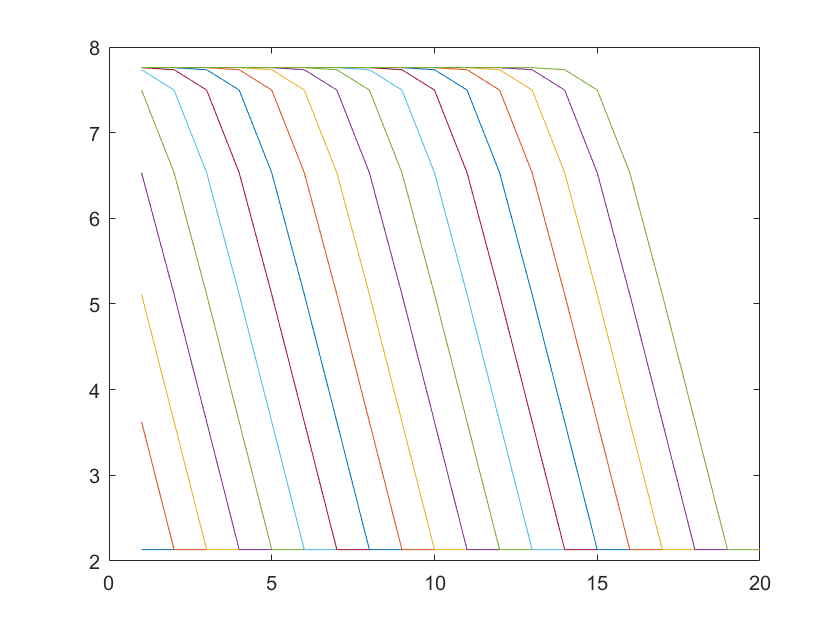


for m = 1:19 
    plot(1:20, dGbox_avr(m, :))
    hold on
end
hold off

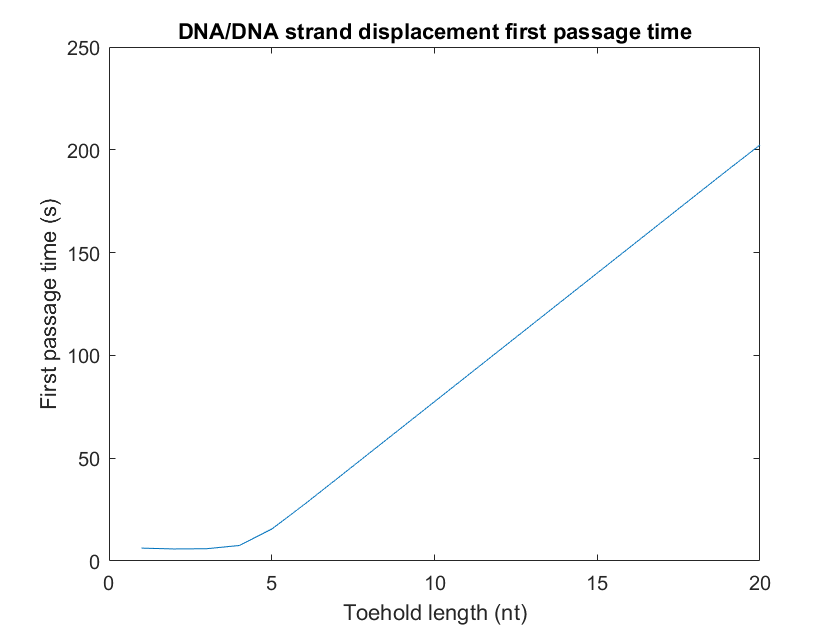


plot(1:20, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

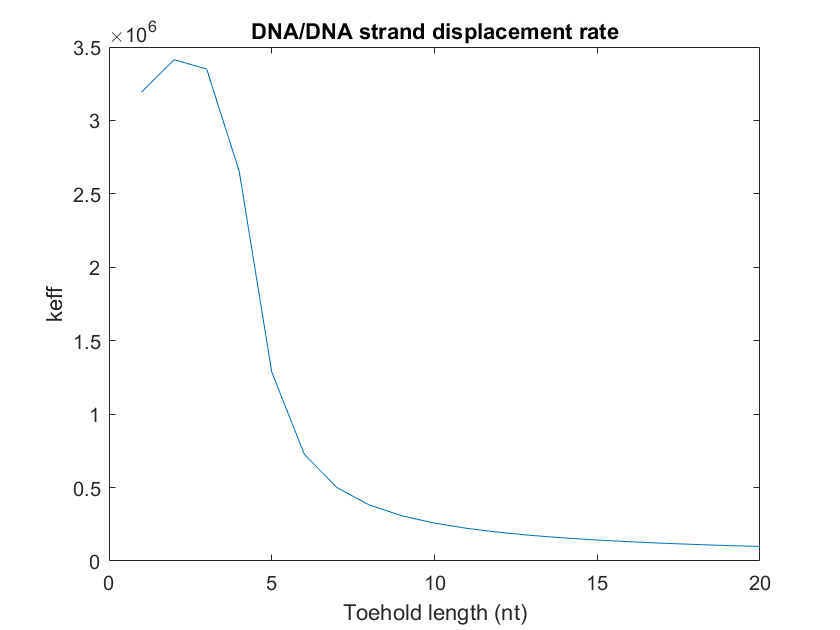


plot(1:20, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

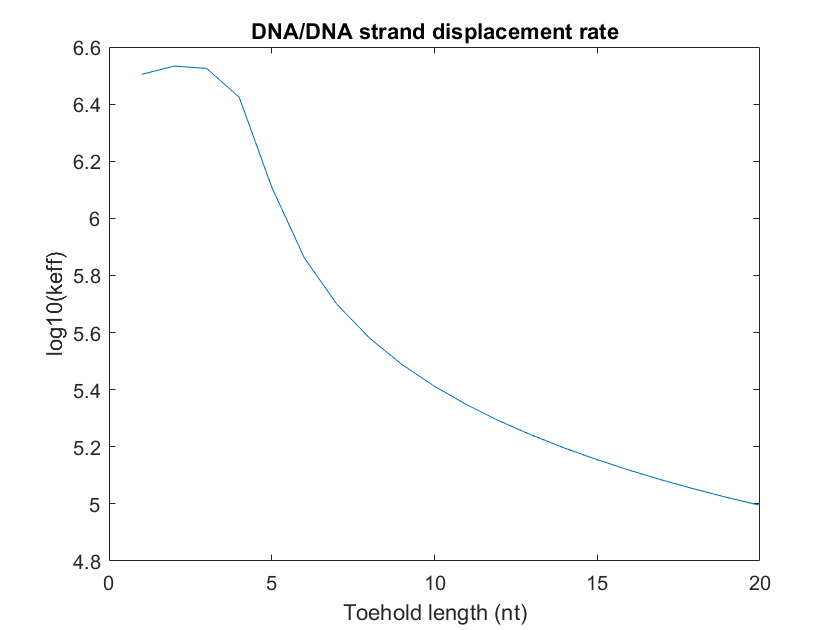


plot(1:20, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate') 

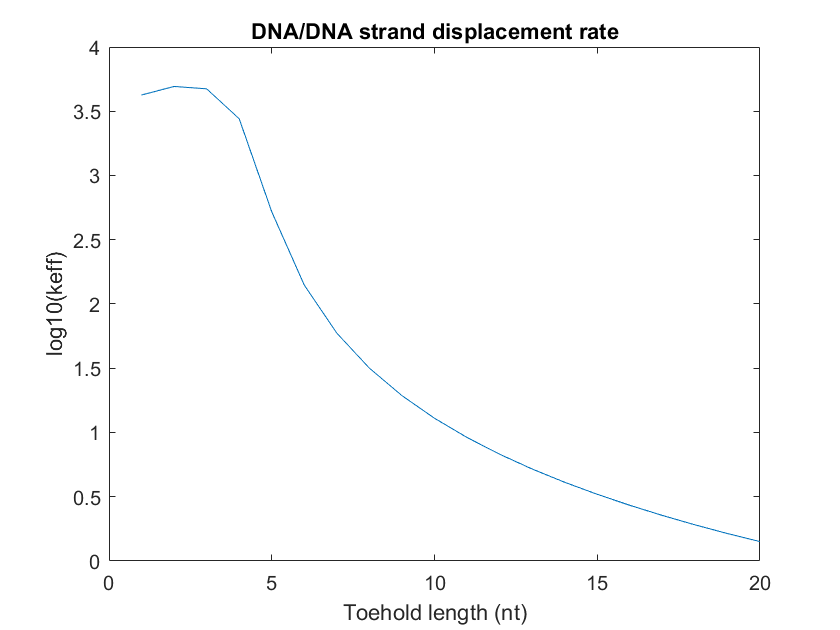


plot(1:20, log(k_eff./k_eff_perf))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate') 